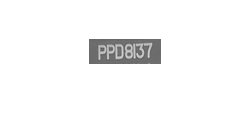

I = rgb2gray(imresize(imread("Plate15.jpg") , [512,512]));

Icrop = imcrop(I , [128 128 256 384]);
corners = detectHarrisFeatures(Icrop);

strongestCorner = corners.selectStrongest(30); 
TF = rmoutliers(strongestCorner.Location,'median');
 
X = min(TF(:,1));
Y = min(TF(:,2));
h = max(TF(:,2)) - Y ;
w = max(TF(:,1)) - X ;

new= imcrop(Icrop , [X-10  Y-5  w+20 h+10]);
imshow(new);

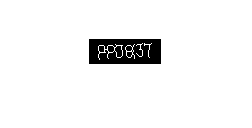


Iafter = imcomplement(imbinarize(uint8(new)));
skel = bwmorph(imcomplement(Iafter),'skel',Inf);
imshow(skel);

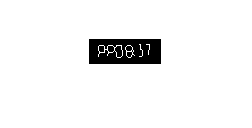

prunned = bwmorph(skel , "spur" , 3);
imshow(prunned);

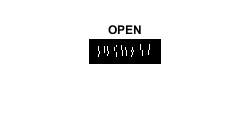


se = strel('rectangle' , [2,1]);
figure,imshow(imopen(prunned , se));title("OPEN"); 

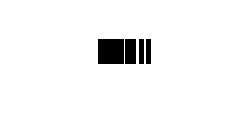


se2 = strel('rectangle' , [160,2]);
sh = prunned;
for k=1:1
   sh =  imdilate(sh,se2);
end



[m,n] = size(sh); 
sh(1:m,1:3) = 0 ; 
imshow(imcomplement(sh));

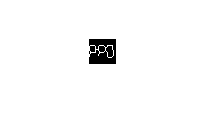

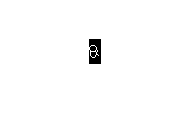

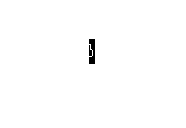

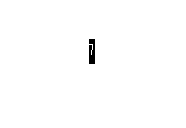

head = 0 ;
tail = 0 ;
character_pos = [] ;
j = 1 ; 
while j < n
    if head == 0 
            if sh(m,j) ~= sh(m,max([1,j-1]))
                head = j ;
            else
                j = j + 1; 
            end
    else
        if head ~= 0 && tail == 0 
            if sh(m,j) == 1 
                j = j + 1;
            else 
                tail = j ;
                figure , imshow(imcrop(prunned , [head 0 tail-head 100]));
                j = j + 1 ; 
                head = 0 ; 
                tail = 0 ;
            end
        else
            j = j + 1; 
            head = 0 ; 
            tail = 0 ; 
        end 
    end 
end